# lora sim script

## lora parameters

%clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
% numSym=round(50000/SF);
numSym=84;

randomData=true;
enableFilters=false;
%channel
perfectChannel=true;%no  awgn
maxDopplerShift=0;%0.5*Fs/(2^SF);%shift has to be less than 0.5*Fs/(2^SF) to have no impact
flatDoppler=false;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=5; %signal to noise ratio in dB
%loops
nLoops=200;
loopSNR=false;
SNRstepsize=2;
loopDoppler=true;
dopplerRate=38;
dopplerStepsize=dopplerRate/Fs;%dopplerrate*sampletime

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=0;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =         2161        3302        3902        2584        1385         718        3175        2014        2952        2686        1883         603         845        1623        1690        3068         800        2435          80        2389        3393        3672        3081        3137        1313        2801        3208         766         513        1094         959        3372         413         483        2367         243         586         873        2131        1550         863         217        3855        2276          41        1851        2846        1280         627        1647


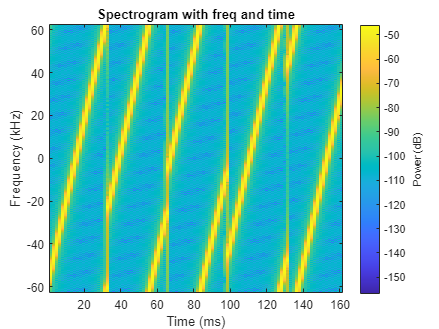

if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end


if enableFilters
    rolloff = 0.25;  % Roll-off factor for the RRC filter
    span = 6;  % Filter span in symbols
    L=8;
    rrcFilter = rcosdesign(rolloff, span, L);
    %impz(rrcFilter)
    txSignal= conv(loraSignal, rrcFilter, 'same');
else
    txSignal = loraSignal;
end

## channel & rx

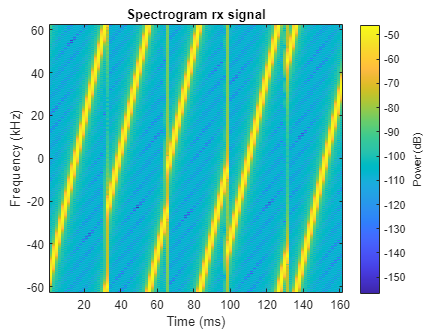

        2174        3331        3938        2646        1463         803        3286        2141        3086        2846        2059         786        1054        1848        1922        3316        1074        2716         377        2712        3723        4018        3453        3516        1708        3222        3636        1210         983        1580        1452        3891         948        1025        2935         827        1177        1490        2764        2190        1519         899         448        2981         772        2589        3600        2060        1414        2450         387         563        1145        2054         984        3166         153        3766        1478         980        3737        2905         990        1293        3494        2839        1439         962        3292        3859         107        2434         537        1508        2805        2454        3693        2347          42         693        1734        3181          79    

%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    else%apply dopper rate
        freqShift=zeros(1,length(t));
        
        for i=1:length(t)
            if loopDoppler
                freqShift(i)=maxDopplerShift+dopplerRate*counter*t(i);
            else
                freqShift(i)=maxDopplerShift+dopplerRate*t(i);
            end
        end
        %freqShift=linspace(dopplerShift,-dopplerShift,length(t));
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    end
    
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = txSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(txSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(txSignal,maxSNR,'measured'));
        end
        %snr
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols

        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    if enableFilters
        matchedFilter = rcosdesign(rolloff, span, L);
        rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
    else
        rxSignalFiltered = rxSignal;
    end
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignalFiltered,SF,numSym);
    if counter==nLoops
        disp(decodedSymbols)
    end
    errors(counter)=sum(messageBits~=decodedBits);
end

lora_ber=errors/dataLength

lora_ber =     0.2044    0.2560    0.2758    0.2956    0.3006    0.3115    0.3323    0.3373    0.3502    0.3333    0.3393    0.3492    0.3611    0.3790    0.3671    0.3750    0.3562    0.3710    0.3611    0.3700    0.3641    0.3651    0.3740    0.3760    0.3780    0.3978    0.3790    0.3919    0.3909    0.3909    0.4067    0.3929    0.3978    0.3849    0.3800    0.4008    0.3919    0.3909    0.3988    0.4077    0.4018    0.4067    0.3909    0.4127    0.4127    0.4157    0.4008    0.3958    0.4087    0.4018


## doppler estimation

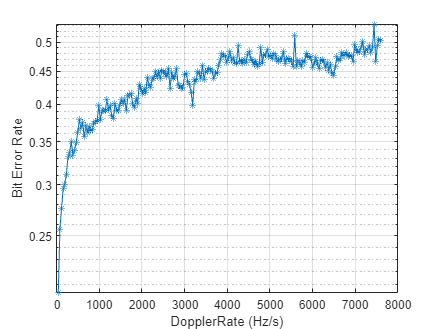

if loopDoppler
    semilogy((1:nLoops)*dopplerRate,lora_ber,'-*')
    xlabel('DopplerRate (Hz/s)')
    ylabel('Bit Error Rate')
    grid on
end


symbolOffset=decodedSymbols-decimalSymbols;
preambleLength=20;
estDopplerOffset=(symbolOffset/2^SF)*Fs

estDopplerOffset = 1.0e+05 *

    0.0040    0.0089    0.0110    0.0189    0.0238    0.0259    0.0339    0.0388    0.0409    0.0488    0.0537    0.0558    0.0638    0.0687    0.0708    0.0757    0.0836    0.0858    0.0906    0.0986    0.1007    0.1056    0.1135    0.1157    0.1205    0.1285    0.1306    0.1355    0.1434    0.1483    0.1505    0.1584    0.1633    0.1654    0.1733    0.1782    0.1804    0.1883    0.1932    0.1953    0.2002    0.2081   -1.0397    0.2151    0.2231    0.2252    0.2301    0.2380    0.2402    0.2451


symbolDuration=(2^SF)/Fs;
indices = round(linspace(1, length(freqShift), preambleLength));

freqShiftValues = freqShift(indices)

freqShiftValues = 1.0e+04 *

    0.0000    0.1101    0.2202    0.3303    0.4404    0.5505    0.6606    0.7707    0.8808    0.9909    1.1010    1.2111    1.3212    1.4313    1.5414    1.6515    1.7616    1.8717    1.9818    2.0919



estDopplerRate=0.5*(estDopplerOffset(preambleLength)-estDopplerOffset(1))/(preambleLength*symbolDuration)

estDopplerRate = 7.2177e+03

symbolTimes=linspace(symbolDuration,preambleLength*symbolDuration,preambleLength)

symbolTimes =     0.0328    0.0655    0.0983    0.1311    0.1638    0.1966    0.2294    0.2621    0.2949    0.3277    0.3604    0.3932    0.4260    0.4588    0.4915    0.5243    0.5571    0.5898    0.6226    0.6554



correctedSymbols=round(decodedSymbols(1:preambleLength)-((estDopplerOffset(1)+estDopplerRate*symbolTimes)/Fs)*2^SF)

correctedSymbols =         2153        3303        3902        2602        1411         744        3219        2066        3003        2756        1961         680         940        1727        1793        3179         929        2564         217        2544


## other method

if false

% Multiply the signal with its complex conjugate
% r = rxSignal .* conj(rxSignal);
% 
% angle(rxSignal)

z = rand(1, 81920) + 1i*rand(1, 81920); % Example complex vector

% Compute the conjugate of the signal
z_conj = conj(z);

% Multiply the signal with its complex conjugate
r = z .* z_conj;
% Number of samples
N = length(r);

% Indices for the 4 phases
indices = [N/4, N/2, 3*N/4, N];
phase1=angle(sum(rxSignal(1:indices(1))))
phase2=angle(sum(rxSignal(indices(1):indices(2))))
phase3=angle(sum(rxSignal(indices(2):indices(3))))
phase4=angle(sum(rxSignal(indices(3):indices(4))))

fd=((phase2+phase4)-(phase1+phase3))/(2*pi*N*(1/Fs))
rd=((phase4-phase3)-(phase2-phase1))/(pi*(N/2)^2 *(1/Fs)^2)
end

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula


lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 1

% lora_ber7=errors/dataLength
% lora_ber10=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    theoryBer12=qfunc((log(12)/log(12))/sqrt(2)*(SNRvec+10*log10((2^12)/12)));
    
    theoryBer7=-0.5+qfunc((log(7)/log(12))/sqrt(2)*(SNRvec+10*log10((2^7)/7)));
    semilogy(SNRvec',theoryBer12,'-*')
    hold on
    semilogy(SNRvec',lora_ber,'-*')
    
    % semilogy(SNRvec',theoryBer7,'-*')
    %hold on
    %semilogy(SNRvec',lora_ber7,'-*')
    
    %semilogy(SNRvec',lora_ber10,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    
    %semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-4 1])
    %legend('theory 12','theory 7','SF 7','SF 9','SF 12')%adjust legend!
    legend( '1','2','3')
    title('BER vs SNR of LoRa and NB-IoT signals')
    
end

%% compare with nbiot


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*2^SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*2^SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/2^SF)*BW